# Parameter Regression

The temperature of a subsea pipeline is measured as hot oil reservoir fluids (water mixed with hydrocarbon liquid and gas) begins flowing. The temperature transmitter (TT) is placed near the well-head at the Flowline End Termination (FLET).

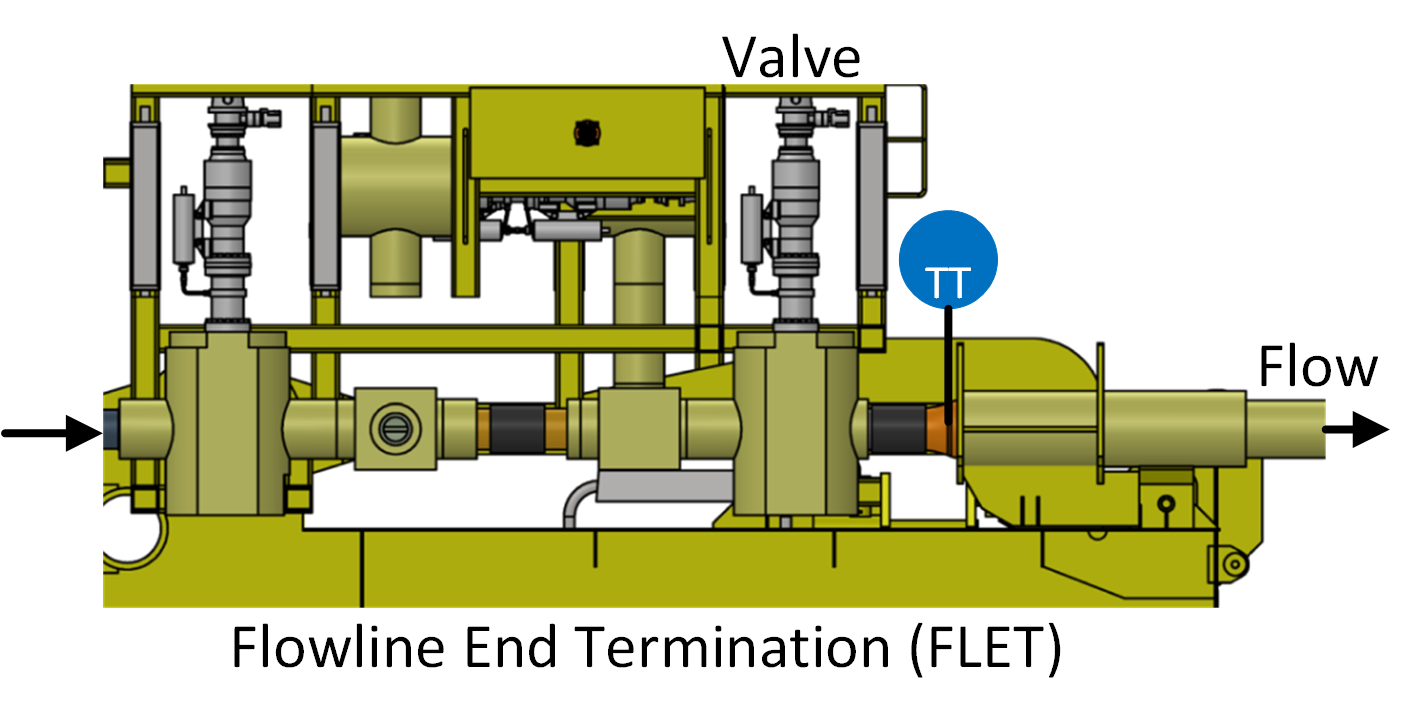

The temperature of the fluid is important to monitor because of the potential for methane hydrates (water and methane) that have the potential to develop under high pressure and cold temperatures. Methanol is added to the fluid to prevent hydrate formation and buildup in the pipeline. If hydrates form and conglomerate, it could lead to pipeline plugging and costly remediation efforts or pipeline abandonment. The following data set is a measurement of fluid temperature during startup of well production. The temperature begins at subsea temperature of 3.6 Celsius and rises over many hours to the well fluid temperature. There is a link to the raw data below with a script that automatically downloads the data file and creates plots of the data.

Use the data to develop a first order plus dead time (FOPDT) model with adjustable parameters $K_p$,$\tau_p$, $\theta_p$. Use a graphical method and optimization method to obtain the unknown parameters and include the data and the two regression results on a single graph.

  [**Pipeline Data File (txt)**](https://apmonitor.com/pdc/uploads/Main/pipeline_data.txt)

Code to download the data and plot the data

url = 'https://apmonitor.com/pdc/uploads/Main/pipeline_data.txt';
A = readmatrix(url);
time_ = A(:,1);
valve_ = A(:,2);
temperature_ = A(:,3);

subplot(2,1,1)
plot(time_, temperature_, 'r-')
ylabel('Temperature (degC)')
subplot(2,1,2)
plot(time_, valve_, 'b--')
ylabel('Valve Position (%)')
xlabel('Time (min)')

taup = 630 - 395
thetap = 1

dy = temperature_(end) - temperature_(1)
du = valve_(end) - valve_(1)
Kp = dy/du

proc_time_y = dy * .62 + temperature_(1) 

subplot(2,1,1)
plot(time_, temperature_, 'r-')
hold on
plot([0,3000],[proc_time_y, proc_time_y])
hold off
ylabel('Temperature (degC)')
subplot(2,1,2)
plot(time_, valve_, 'b--')
ylabel('Valve Position (%)')
xlabel('Time (min)')

taup = 630-395

## Regress Parameters

viewSolution(false)

Use the functions below to regress the FOPDT Parameters and graph the results

x0 = [.42 235 1];  % Initial guesses [gain, process time, dead time]

initial_obj = objective(x0, time_, valve_, temperature_)  % initial obj
fopdt_params = fminsearch(@(x)objective(x, time_, valve_, temperature_), x0)  % Regress parameters
optimized_obj = objective(fopdt_params, time_, valve_, temperature_)  % final obj

y_i = sim_model(x0, time_, valve_, temperature_)  % simulate initial guess
y_fopdt = sim_model(fopdt_params,time_, valve_, temperature_)  % simulate regressed parameters

% plot
figure(2)
subplot(2,1,1)
plot(time_, temperature_, 'r-')
hold on
plot(time_, y_fopdt, 'b-')
hold on
plot(time_, y_i, 'b--')
hold off
xlabel('Time (s)')
legend({'Data' 'FOPDT 1' 'Initial Guess' })
ylabel('Temperature')
subplot(2,1,2)
plot(time_, valve_, 'r-')

function dydt = fopdt(t, y, u, tvals, Km,taum,thetam, yp1, u1)
    % arguments
    %  t      = time
    %  y      = output
    %  Km     = model gain
    %  taum   = model time constant
    %  thetam = model dead time constant
    %  yp1    = initial output value
    %  u1     = initial input value

    try
        if (t-thetam) <= 0
            um = u1;
        else
            um = interp1(tvals, u, t-thetam);
        end
    catch 
        disp('Error with time extrapolation: ' + t )

        um = u1;
    end
    % calculate derivative
    dydt = (-(y-yp1) + Km * (um-u1))/taum;
end

% simulate FOPDT model with x=[Km,taum,thetam]
function ym = sim_model(x, time_, u_, yp_)
    % input arguments
    Km = x(1);
    taum = x(2);
    thetam = x(3);
    
    ns = length(time_);
    yp1 = yp_(1);
    u1 = u_(1);
    
    % storage for model values
    ym = zeros(ns, 1);  % model
    % initial condition
    ym(1) = yp1;
    % loop through time steps    
    for i = 1:ns-1
        ts = [time_(i),time_(i+1)];
        [~, ys] = ode45(@(t, y) fopdt(t, y, u_, time_, Km,taum,thetam, yp1, u1), ts, ym(i));
        ym(i+1) = ys(end);
    end
end

function obj = objective(x_arg, time_, u_, yProcess)
    % simulate model
    ym = sim_model(x_arg, time_, u_, yProcess); 
    % calculate objective with sum squared error
    obj = sum((ym-yProcess).^2)*1000;
end

### Solution

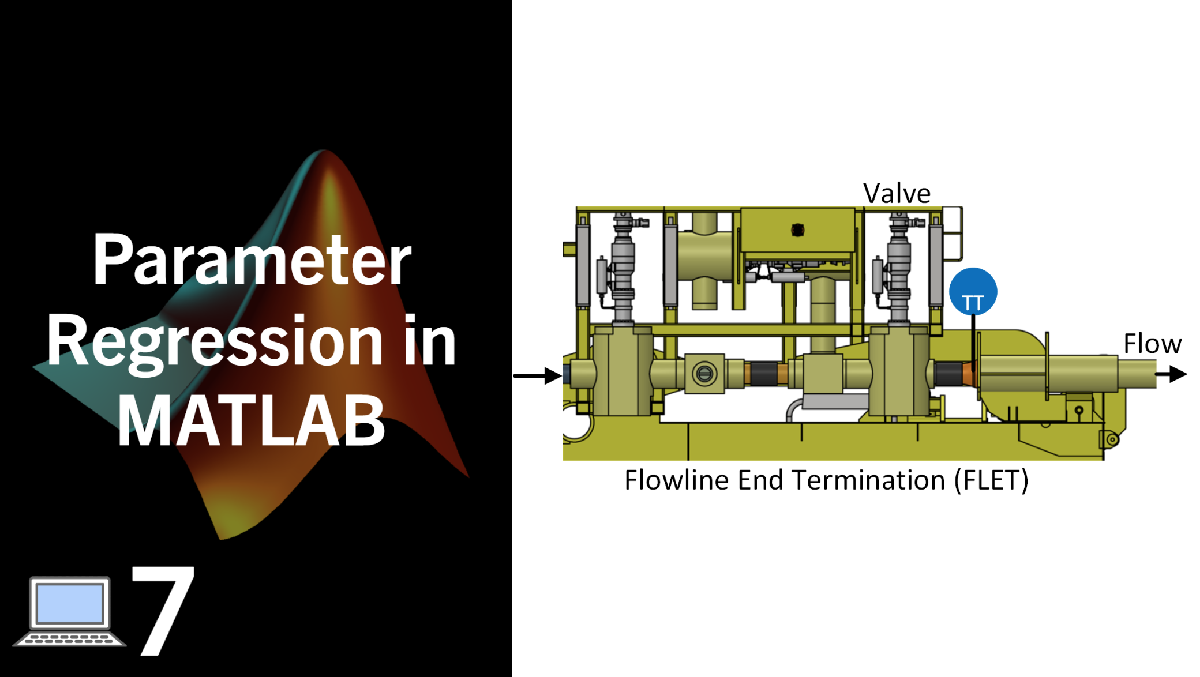

### [View Solution Video](https://youtu.be/Cm8_MYj1pWE)

function viewSolution(view)
if view
	disp("x0 = [.45 500 30];  % Initial guesses" + newline + ...
	     "" + newline + ...
	     "initial_obj = objective(x0, time_, valve_, temperature_)  % initial obj" + newline + ...
	     "fopdt_params = fminsearch(@(x)objective(x, time_, valve_, temperature_), x0)  % Regress parameters" + newline + ...
	     "optimized_obj = objective(fopdt_params, time_, valve_, temperature_)  % final obj" + newline + ...
	     "" + newline + ...
	     "y_i = sim_model(x0, time_, valve_, temperature_)  % simulate initial guess" + newline + ...
	     "y_fopdt = sim_model(fopdt_params,time_, valve_, temperature_)  % simulate regressed parameters" + newline + ...
	     "" + newline + ...
	     "% plot" + newline + ...
	     "figure(2)" + newline + ...
	     "subplot(2,1,1)" + newline + ...
	     "plot(time_, temperature_, 'r-')" + newline + ...
	     "hold on" + newline + ...
	     "plot(time_, y_fopdt, 'b-')" + newline + ...
	     "plot(time_, y_i, 'b--')" + newline + ...
	     "xlabel('Time (s)')" + newline + ...
	     "hold off" + newline + ...
	     "legend({'Data' 'FOPDT 1' 'Initial Guess' })" + newline + ...
	     "ylabel('Temperature')" + newline + ...
	     "subplot(2,1,2)" + newline + ...
	     "plot(tm, valve_, 'r-')" + newline + ...
	 "end")
end
end